clear 
clc

**Generate the true state sequence z's and the observation sequence x's**

num_samples = 1000;
% normal distribution:0, 
% uniform distribution:1
distribution = 1;

% GENERATE true underlying state sequence z
z0 = 0;
gamma = 0.5; 

if distribution == 0
    % normal distribution (0,1)
    delta = normrnd(0,1,[1,1000]);
    
elseif distribution == 1
    % uniform distribution [0, 1]
    delta = unifrnd(0,1,[1, 1000]);
end

true_z = zeros(1, num_samples) ;
true_z(1) = gamma*z0 + delta(1);

for i=2:num_samples
    true_z(i) = gamma*true_z(i-1) + delta(i);
end

%=========================================

% GENERATE x
x = zeros(1, num_samples);

if distribution == 0
    for i=1:num_samples
        % normal distribution (z, 1)
        x(i) = normrnd(true_z(i), 1);
    end
  
elseif distribution == 1
    for i=1:num_samples
        % uniform distribution (2z, 0)
        if true_z(i) < 0
            x(i) = unifrnd(2*true_z(i), 0);
        else 
            x(i) = unifrnd(0, 2*true_z(i));
        end

    end
end

% mean x, mean true_z
mean(x)

ans = 0.9652

mean(true_z)

ans = 0.9898

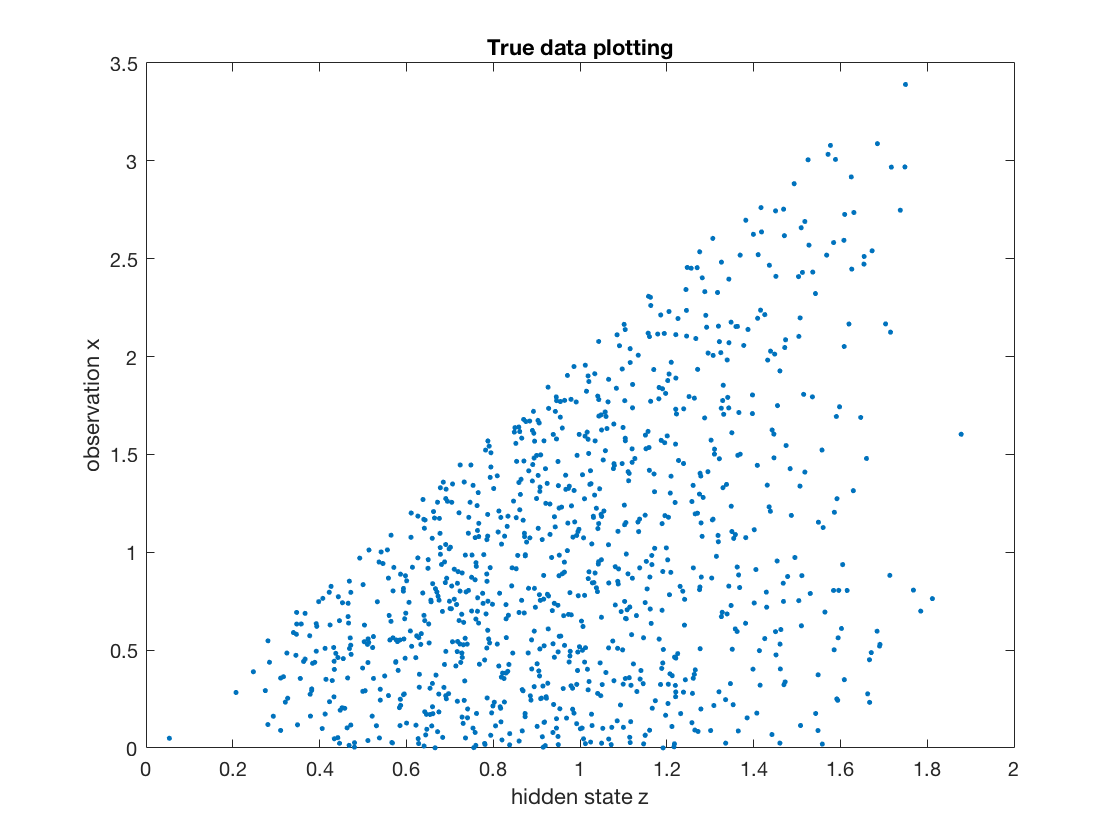


% visualize the original data 
figure(1)
plot(true_z, x,'.')
title("True data plotting")
xlabel('hidden state z')
ylabel('observation x')

**Initialization:** Given x, find x - mean(x) and initialize random gamma.

gamma = rand;

% gamma is non zero
while(gamma == 0)
    gamma = rand;
end

mean_x = mean(x);
for i=1:num_samples
    x(i) = x(i) - mean_x;
end

mean(x)

ans = 3.6127e-16

**Repeat until covergence:**

**Step 1:** Given z, z_0 = 0 and \gamma, we adjust z to minimize the variance of y and w

**Step 2:** Given x, z, using the poor man procedure, we adjust  \gamma to minimize mean of y and w.

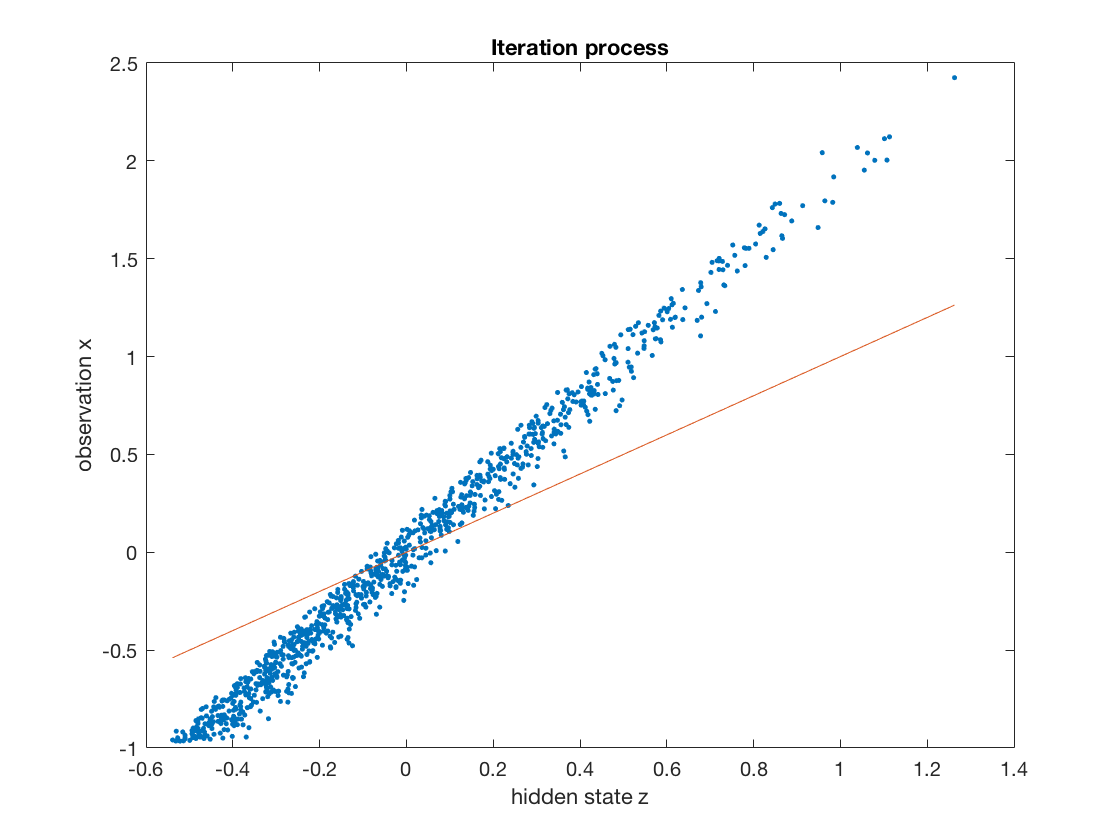

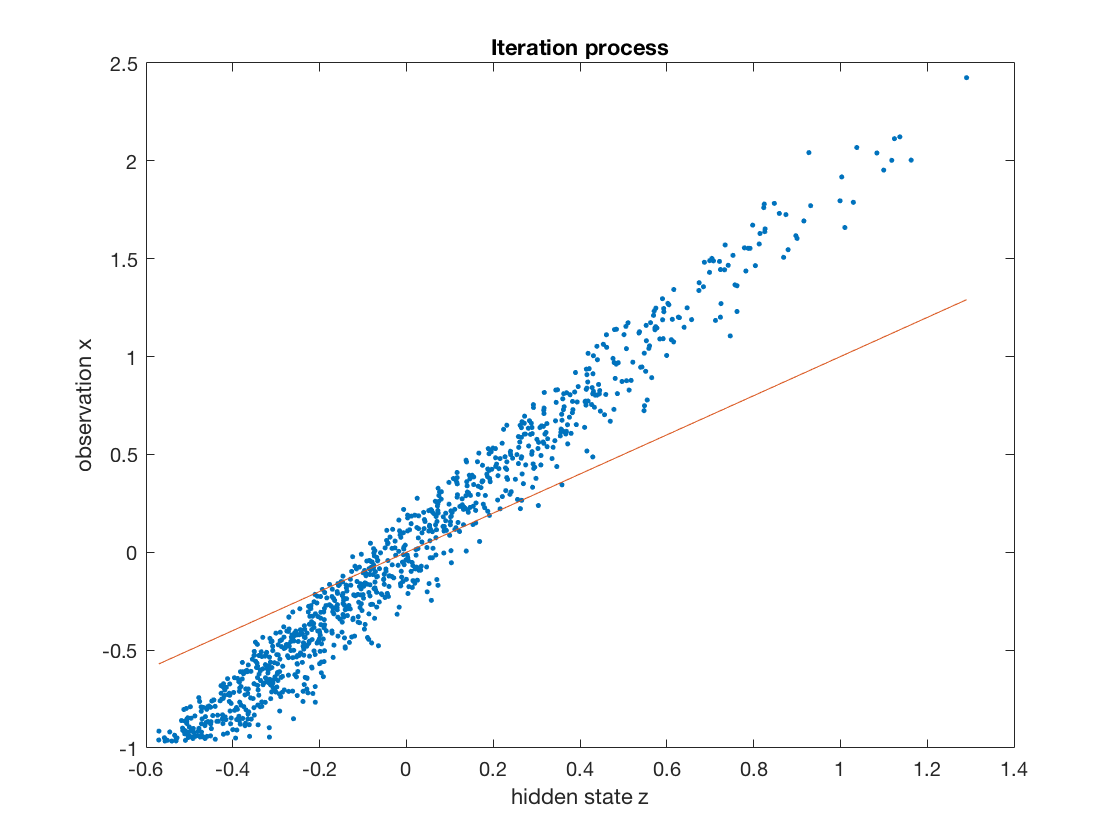

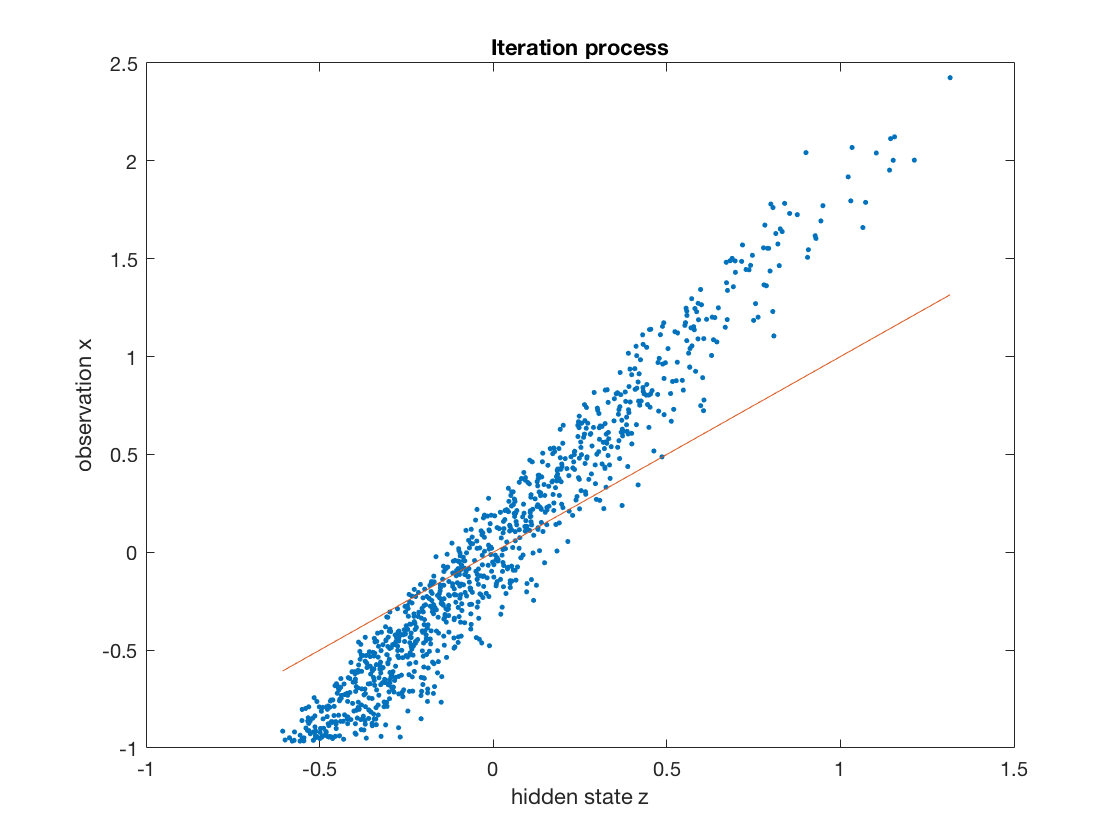

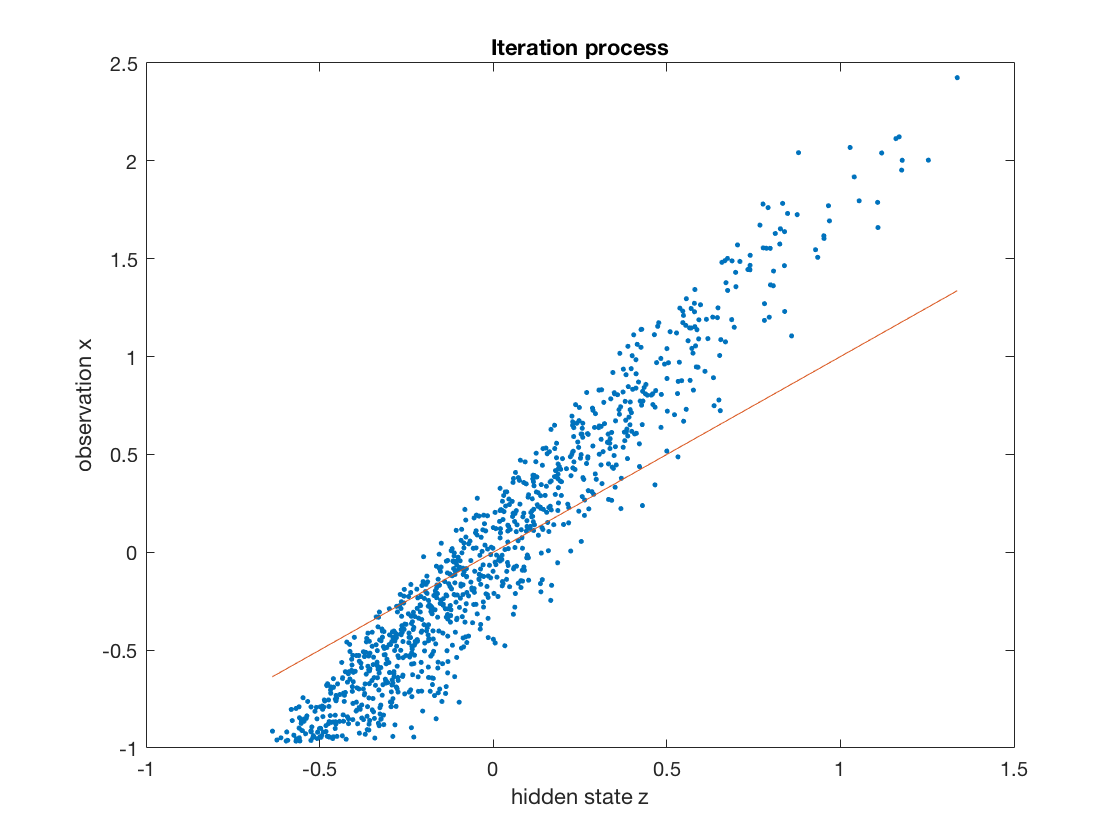

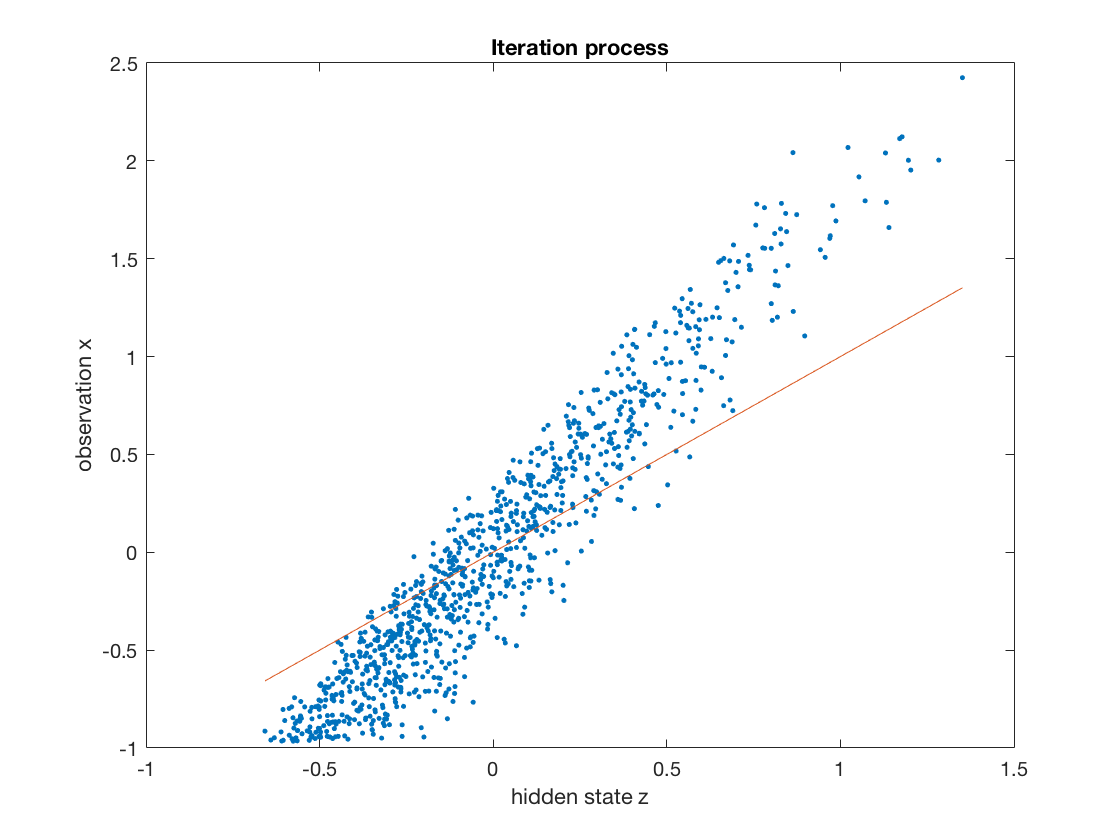

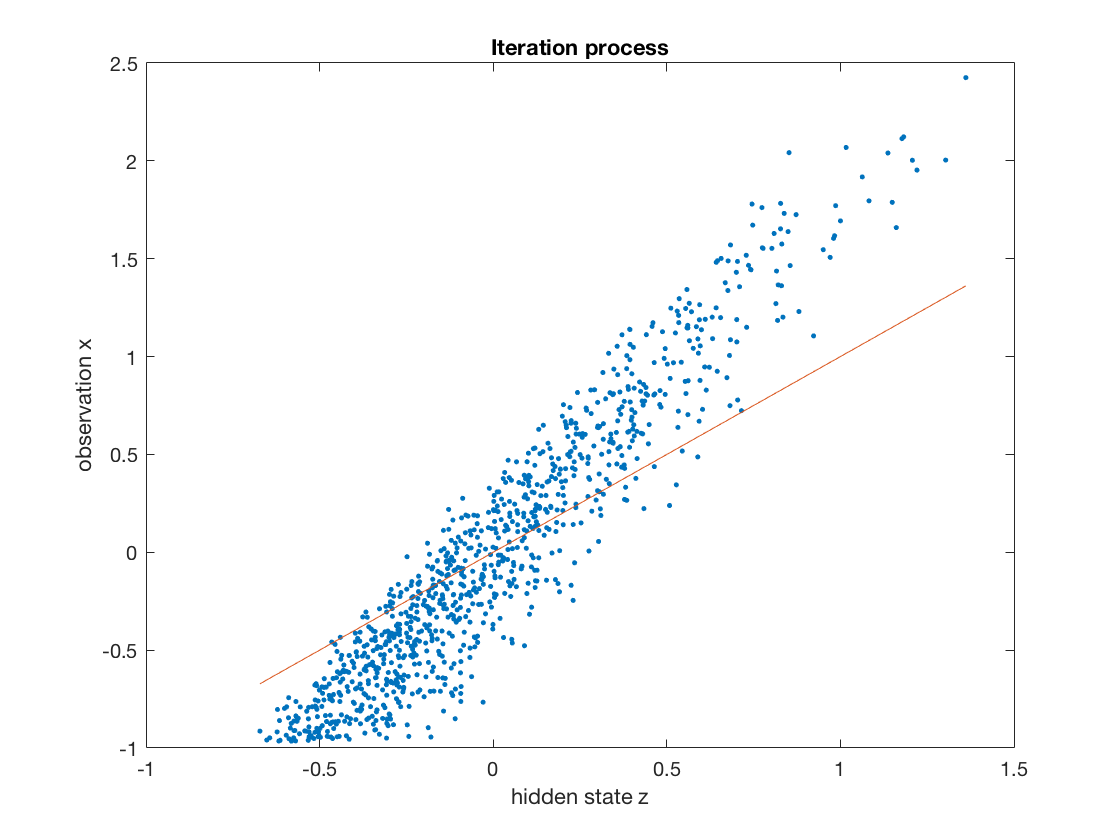

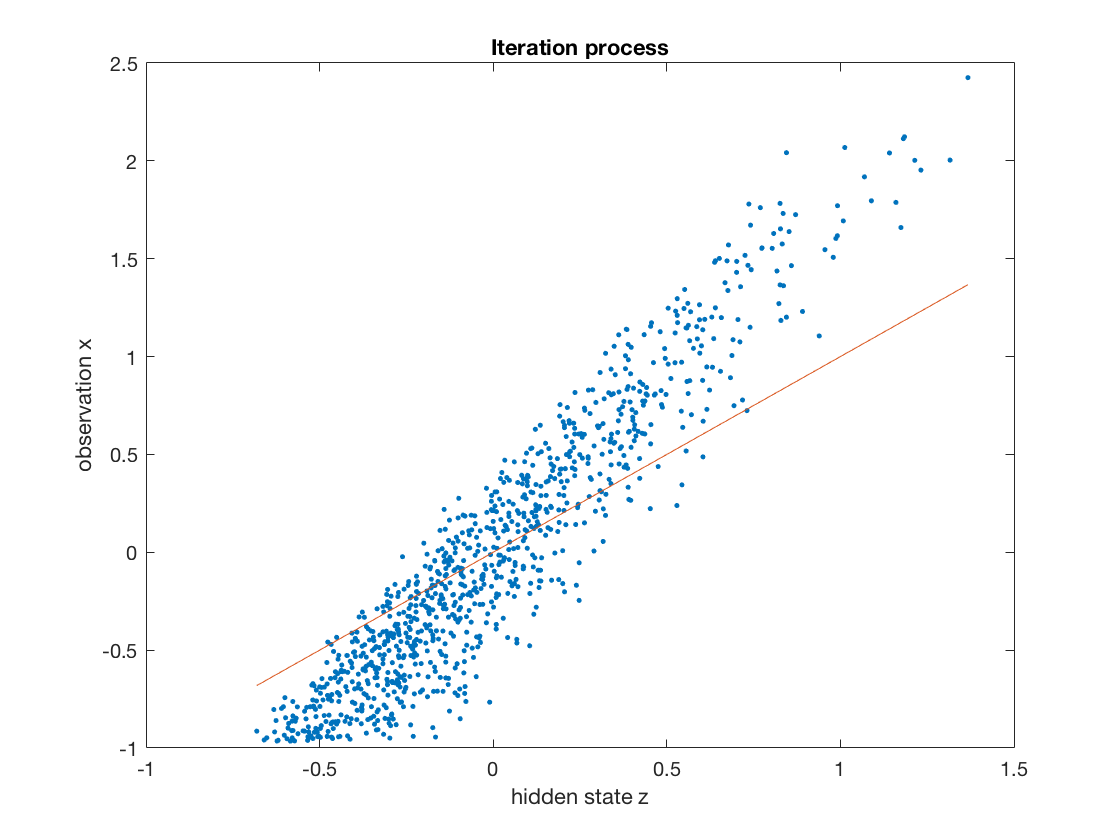

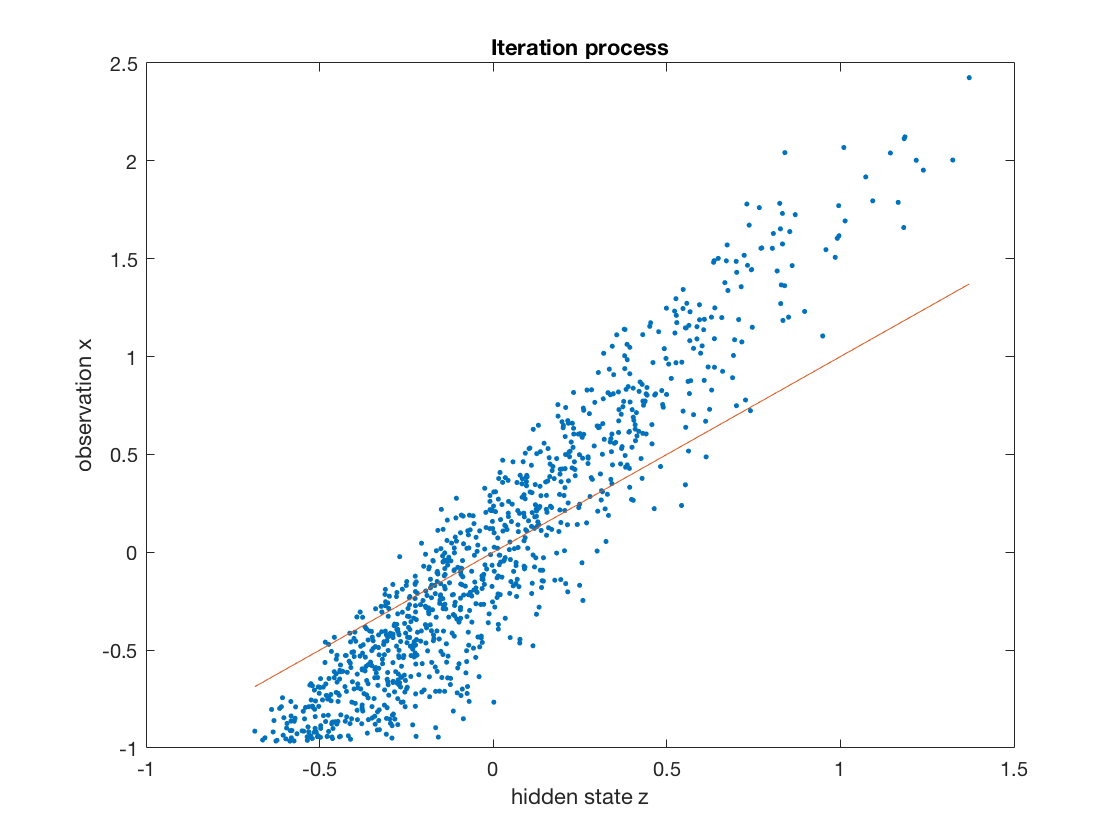

threshold = 0.000000001;
all_MSE = zeros(1, 0);
cnt = 0;
while (true)
    
    cnt = cnt+1;
    
    % STEP 1
    % calculate A, c in Az = c
    u = -2 * gamma;
    v = 4+ 2 * gamma^2;
    c = zeros(1, num_samples);
    for i=1:num_samples
        c(i) = 2*x(i);
    end
    
    
    % calculate LU decomposition of A
    r = zeros(1, num_samples);
    t = zeros(1, num_samples);
    
    t(1) = v;
    for i=2:num_samples
        r(i) = u/t(i-1);
        if i < num_samples
            t(i) = v - r(i)*u ;
        else t(i) = v + u - r(i)*u ;
        end
    end
    
    
    % calculate z
    % Az = LUz = C. Let Uz = D => LD = C 
    % Calculate D
    d = zeros(1, num_samples);
    d(1) = c(1);
    
    for i=2:num_samples
        d(i) = c(i) - r(i)*d(i-1);
    end
    % Calculate Z
    curr_z = zeros(1, num_samples);
    curr_z(num_samples) = d(num_samples)/t(num_samples);
    for i = num_samples-1:-1:1
       curr_z(i) = (d(i) - u*curr_z(i+1))/t(i);
    end
    
    if cnt > 1
        error = abs(z-curr_z).^2;
        MSE = sum(error(:)) / num_samples;
        all_MSE = [all_MSE MSE];
        z = curr_z;
       
        if (MSE < threshold)
            break
        end
    end
    
    z = curr_z;
    
    % STEP 2
    % calcualte gamma
    z_prev = zeros(1, num_samples);
    z_prev(1) = z0;
    for i=2:num_samples
        z_prev(i) = z(i-1);
    end
    
    gamma = pinv(z_prev * z_prev') * (z_prev * z');
    
    % visualize the original data 
    figure(cnt)
    x_hat = z';
    plot(z, x,'.')
    title("Iteration process")
    xlabel('hidden state z')
    ylabel('observation x')
    hold on
    % Plot the best fit line.
    plot(z, x_hat)
   
end

% mean of z
mean(z)

ans = 2.1940e-04

% Compare with the true z
real_error = abs(z-true_z).^2;
real_MSE = sum(real_error(:)) / num_samples

real_MSE = 1.1003